LAB Week 8

Name: Hajra Yousf

Student ID: 47836512

Task 1 a)

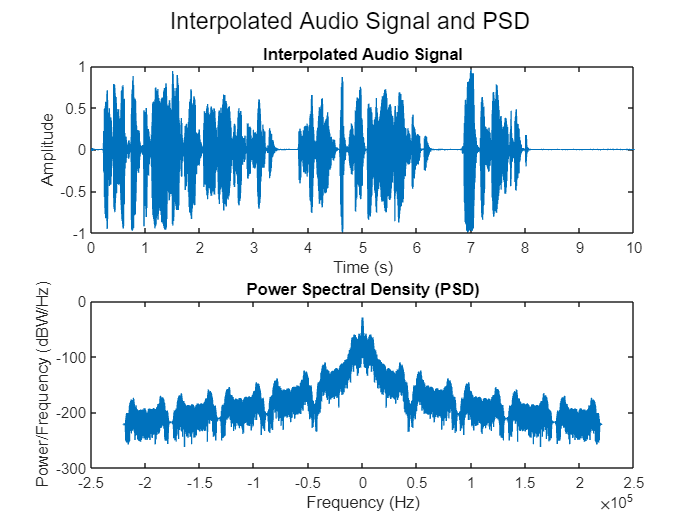

[data, fs] = audioread('Audio1.wav');

t = (0:length(data)-1) / fs;
interp_factor = 10;
t_new = linspace(0, t(end), length(data) * interp_factor);
data_interpolated = interp1(t, data, t_new, 'spline');
fs_new = fs*interp_factor;

figure;

subplot(2, 1, 1);
plot(t_new, data_interpolated);
title('Interpolated Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

N = length(data_interpolated);
X = fft(data_interpolated);
Pxx = (1/(fs_new*N)) * abs(X).^2;
f = (-fs_new/2):(fs_new/N):(fs_new/2-fs_new/N);
psd_dB = 10*log10(fftshift(Pxx));

subplot(2, 1, 2);
plot(f, psd_dB);
title('Power Spectral Density (PSD)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dBW/Hz)');

sgtitle('Interpolated Audio Signal and PSD');

b)

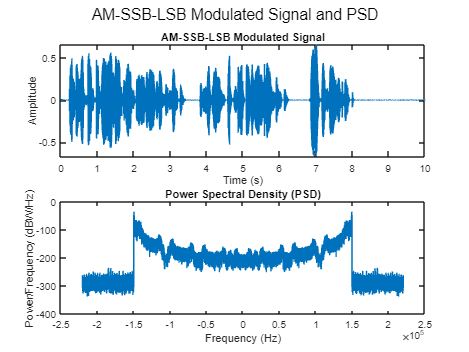

fc = 150e3;
s_LSB = 0.5 * ssbmod(data_interpolated,fc,fs_new);

N = length(s_LSB);
X = fft(s_LSB);
Pxx = (1/(fs_new*N)) * abs(X).^2;
f = (-fs_new/2):(fs_new/N):(fs_new/2-fs_new/N);
psd_dB = 10*log10(fftshift(Pxx));

figure;
subplot(2, 1, 1);
plot(t_new, s_LSB);
title('AM-SSB-LSB Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(f, psd_dB);
title('Power Spectral Density (PSD)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dBW/Hz)');

sgtitle('AM-SSB-LSB Modulated Signal and PSD');

c)

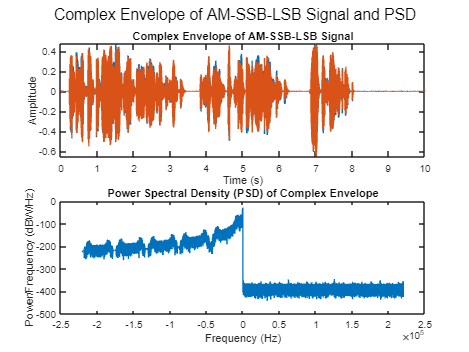

m_hilbert = imag(hilbert(data_interpolated));

s_tilde_LSB = 0.5 * (data_interpolated - 1j * m_hilbert);

figure;
subplot(2, 1, 1);
plot(t_new, real(s_tilde_LSB));
hold on;
plot(t_new, imag(s_tilde_LSB));
hold off;
title('Complex Envelope of AM-SSB-LSB Signal');
xlabel('Time (s)');
ylabel('Amplitude');

N = length(s_tilde_LSB);
X = fft(s_tilde_LSB);
Pxx = (1/(fs_new*N)) * abs(X).^2;
f = (-fs_new/2):(fs_new/N):(fs_new/2-fs_new/N);
psd_dB = 10*log10(fftshift(Pxx));

subplot(2, 1, 2);
plot(f, psd_dB);
title('Power Spectral Density (PSD) of Complex Envelope');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dBW/Hz)');

sgtitle('Complex Envelope of AM-SSB-LSB Signal and PSD');

d)

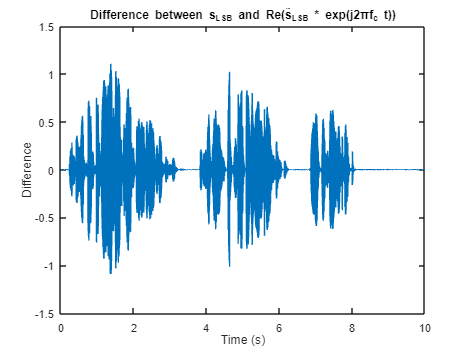

s_complex_env  = real(s_tilde_LSB.*exp(1j*2*pi*fc*t_new));

diff_signal = s_LSB - s_complex_env;

figure;
plot(t_new, diff_signal);
title('Difference between s_{LSB} and Re(s̃_{LSB} * exp(j2πf_c t))');
xlabel('Time (s)');
ylabel('Difference');

TASK 2

a)

% Define parameters
fc = 98.5e6; % Center frequency of the FM radio station in Hz
fs = 960e3; % Sampling rate in Hz
L = 96000; % Number of samples per frame
num_frames = 50; % Number of consecutive frames to record
duration = 5; % Total recording duration in seconds

% Initialize RTL-SDR device
sdrReceiver = comm.SDRRTLReceiver('CenterFrequency', fc, 'SampleRate', fs, 'SamplesPerFrame', L);

% Preallocate storage for recorded frames
recorded_frames = zeros(L, num_frames);

% Record frames
for frame = 1:num_frames
    recorded_frames(:, frame) = step(sdrReceiver);
end

% Release RTL-SDR device
release(sdrReceiver);


b)

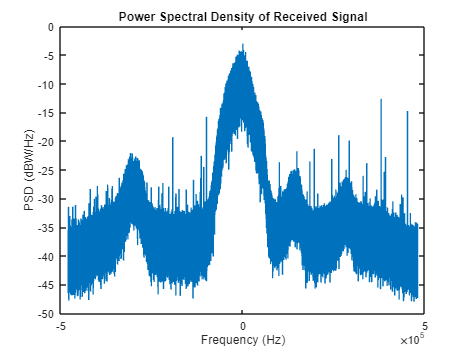

% Combine recorded frames into a single complex-valued signal
combined_frames = reshape(recorded_frames, [], 1);

% Compute Power Spectral Density (PSD) of the received signal
psd_signal = pwelch(combined_frames, [], [], [], fs, 'centered', 'power');

% Convert PSD to dBW/Hz
psd_signal_dB = 10*log10(psd_signal);

% Plot the PSD
figure;
frequencies = linspace(-fs/2, fs/2, length(psd_signal));
plot(frequencies, psd_signal_dB);
title('Power Spectral Density of Received Signal');
xlabel('Frequency (Hz)');
ylabel('PSD (dBW/Hz)');

c)

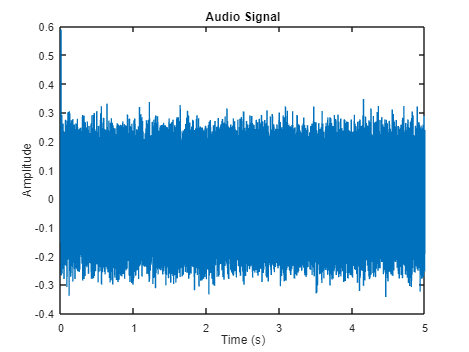



% Demodulate FM signal
fm_demodulated = diff(angle(combined_frames)); % Phase differentiation

% Downsample the demodulated signal to fs = 48 kHz
fs_downsampled = 48e3;
downsample_factor = fs/fs_downsampled;
audio_signal = decimate(fm_demodulated, downsample_factor);

% Create time vector for plotting
t = (0:length(audio_signal)-1) / fs_downsampled;

% Plot audio signal as a function of time
figure;
plot(t, audio_signal);
title('Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');


% Play audio signal
soundsc(audio_signal, fs_downsampled);

TASK 3

a)

signal analysis # 1

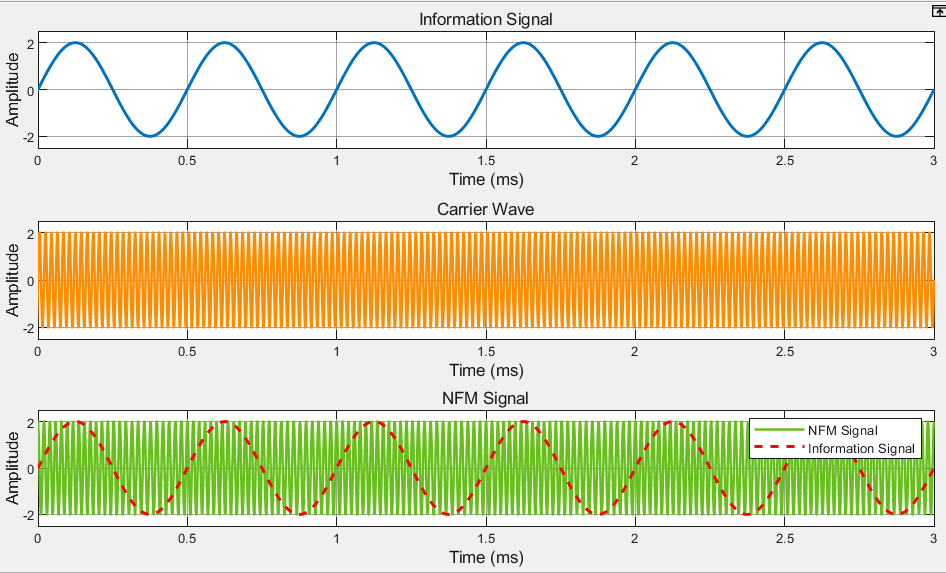

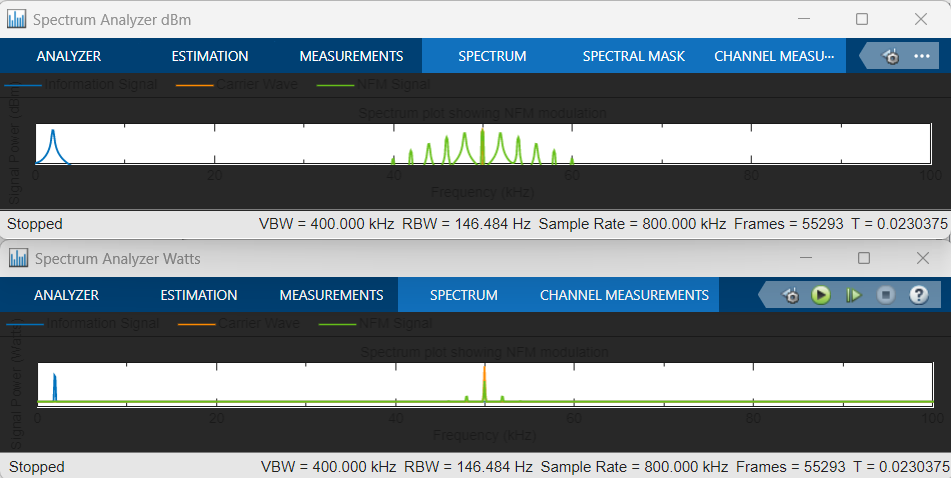

signal analysis # 2

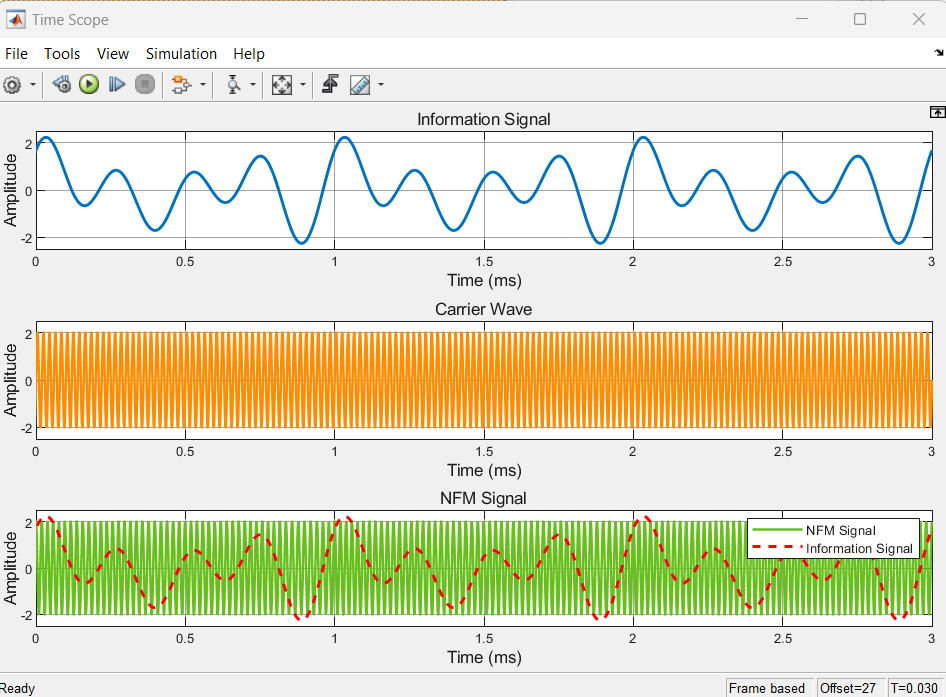

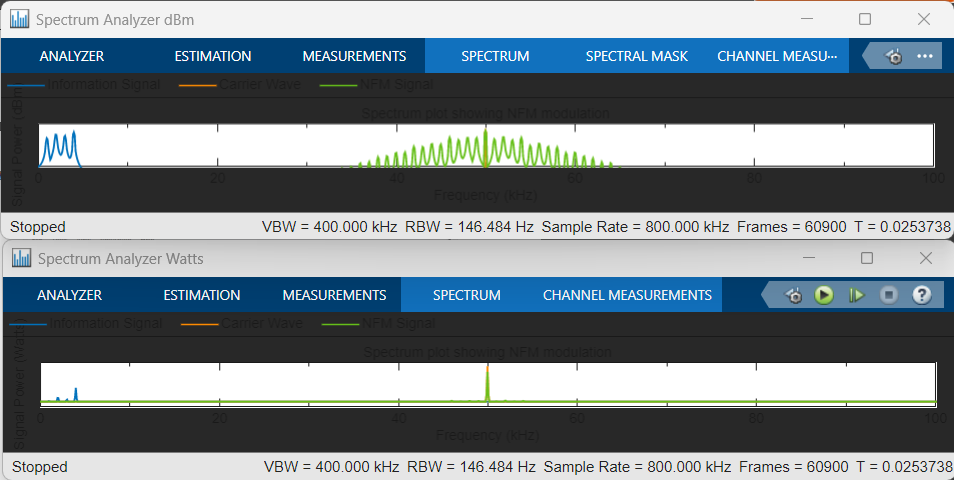

b)

signal analysis # 1

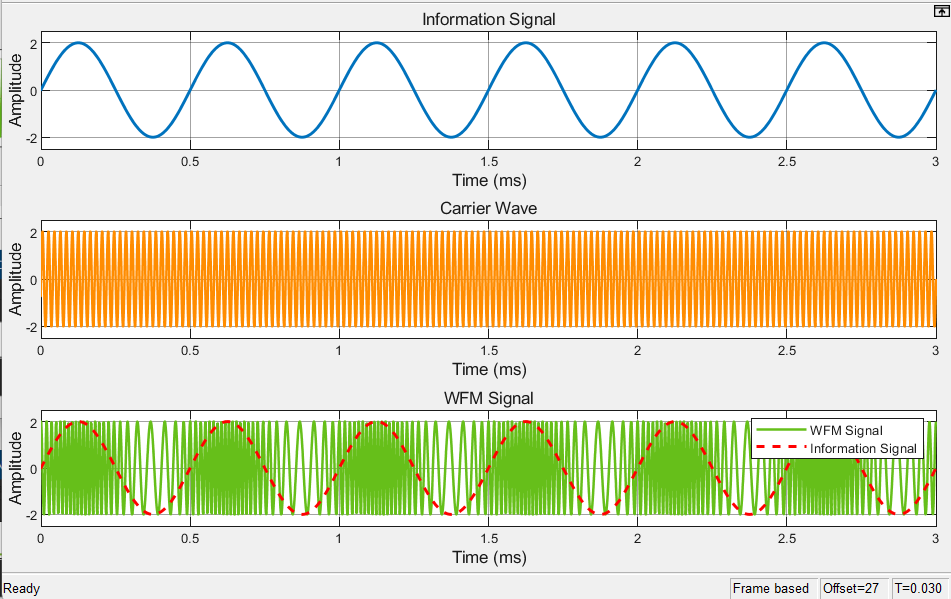

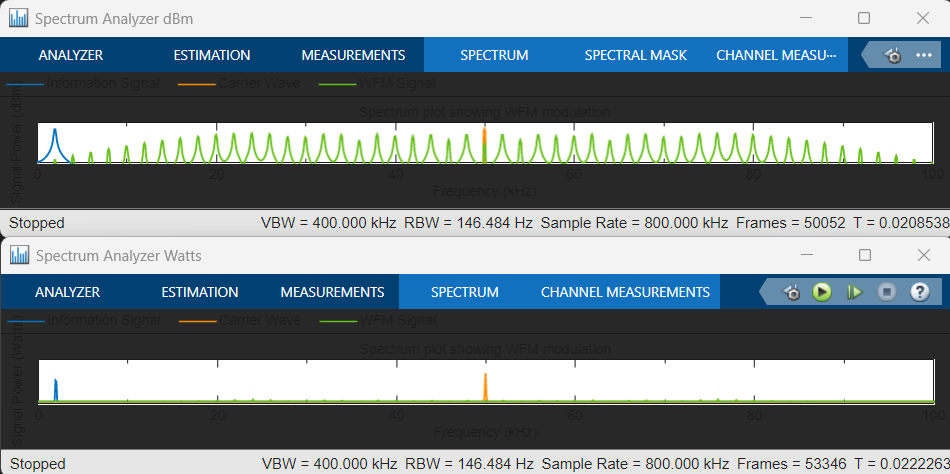

signal analysis # 2

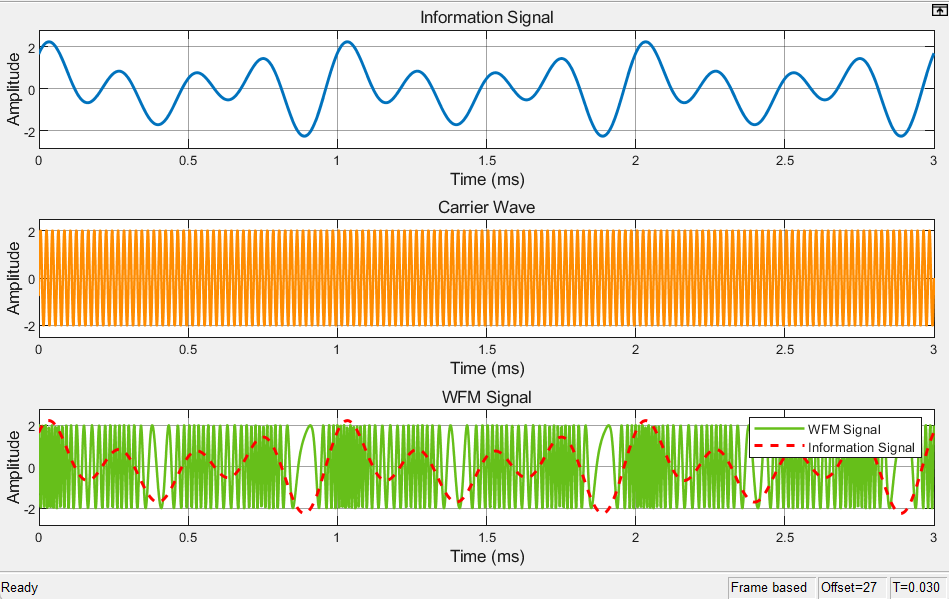

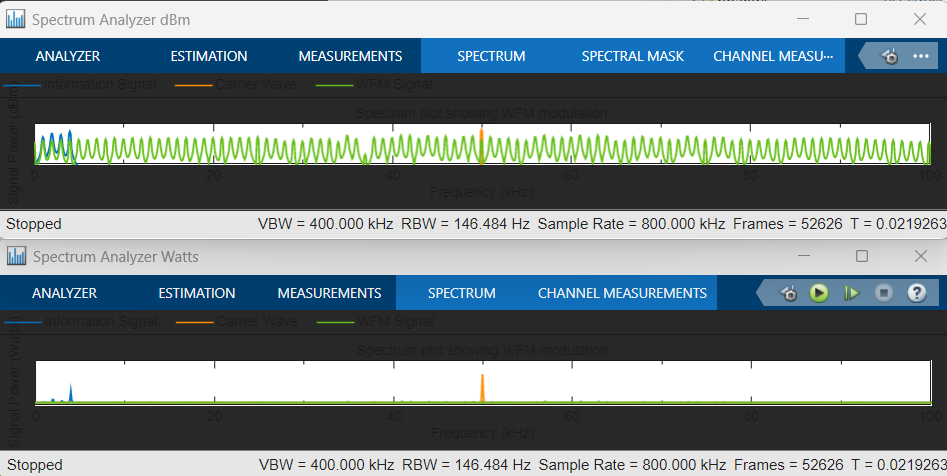

c)